## Signal Model (Q2)

Generating the data

M = 5;              % Number of antennas
N = 20;             % Number of samples
theta = [-20 30]';  % Source angles
f = [0.1 0.3]';     % Normalized frequencies
SNR = 1000;           % Signal to noise ratio in dB
Delta = 0.5;        % Antenna aperture in wavelengths
d = length(theta);  % Number of sources
[X,A,S] = gendata(M, N, Delta, theta, f, SNR);

Check the singular values of X matrix

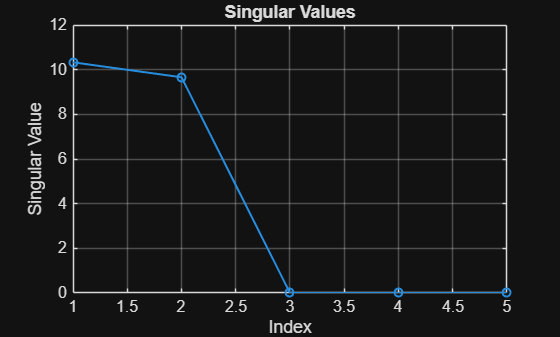

[U, S, V] = svd(X, "econ"); % Since M < N, we will get MxM Sigma
singular_values = diag(S);
plot_singular_values(singular_values);

### Double the number of samples

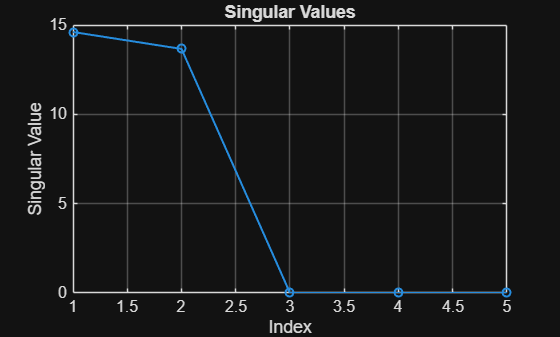

N2 = 20 * 2; % Number of samples doubled
[X_2N, ~, ~] = gendata(M, N2, Delta, theta, f, SNR);
[~, S_2N, ~] = svd(X_2N, "econ"); % Since M < 2N, we will get MxM Sigma
singular_values_2N = diag(S_2N);
plot_singular_values(singular_values_2N);

### Double the number of antennas

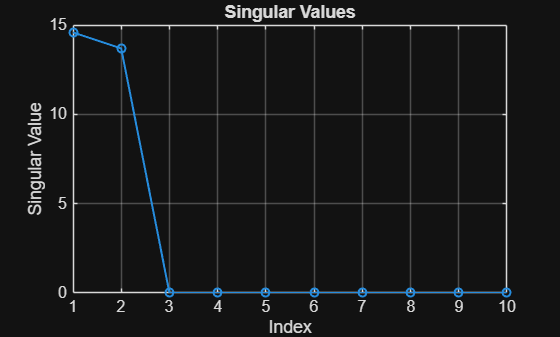

M2 = M * 2; % Number of samples doubled
[X_2M, ~, ~] = gendata(M2, N, Delta, theta, f, SNR);
[~, S_2M, ~] = svd(X_2M, "econ"); % Since 2M < N, we will get MxM Sigma
singular_values_2M = diag(S_2M);
plot_singular_values(singular_values_2M); xlim([1, 2*M]);

### Angles between sources becomes small

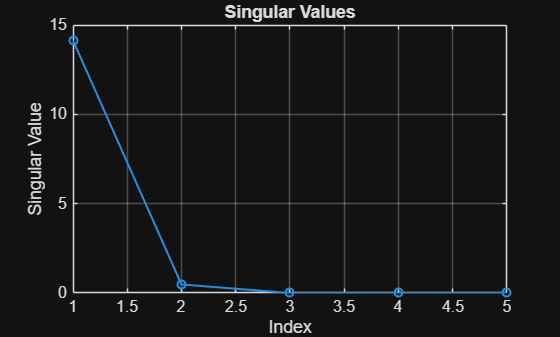

theta_small = [29 30]';   % Source angles
[X_theta_small, ~, ~] = gendata(M, N, Delta, theta_small, f, SNR);
[~, S_theta_small, ~] = svd(X_theta_small, "econ");
singular_values_theta_small = diag(S_theta_small);
plot_singular_values(singular_values_theta_small);

### Frequency difference becomes small

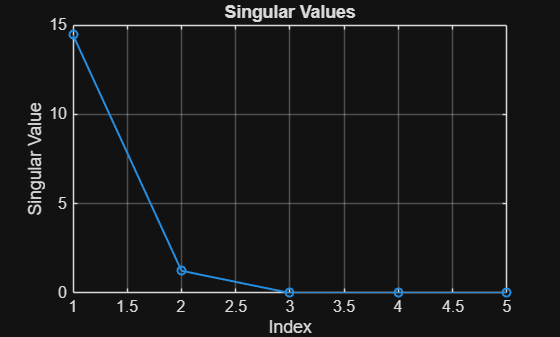

f_small = [0.295 0.3]';     % Normalized frequencies
[X_f_small, ~, ~] = gendata(M, N, Delta, theta, f_small, SNR);
[~, S_f_small, ~] = svd(X_f_small, "econ");
singular_values_f_small = diag(S_f_small);
plot_singular_values(singular_values_f_small);

## Estimation of Directions (Q2)

Generate data

clear;
M = 5;              % Number of antennas
N = 20;             % Number of samples
theta = [-20 30]';  % Source angles
f = [0.1 0.3]';    % Normalized frequencies
SNR = 1000;         % Signal to noise ratio in dB (Too high for verification purpose)
Delta = 0.5;        % Antenna aperture in wavelengths
d = length(theta);  % Number of sources
[X,A,S] = gendata(M, N, Delta, theta, f, SNR);

% Estimate DoA using esprit
estimated_thetas = esprit(X, d) % Function assumes delta is by default 0.5

estimated_thetas =    30.0000
  -20.0000


## Estimation of Frequencies (Q3)

% Estimate source frequencies using esprit
estimated_f = espritfreq(X, d)

estimated_f =     0.3000
    0.1000


## Joint estimation of directions and frequencies (Q3)

m = 15;
[f, theta] = joint_diagonalization_selection(X, m)

f =     0.3000
    0.1000


theta =    30.0000
  -20.0000


[f, theta] = joint_diagonalization_parameter_averaging(X, m)

f =     0.3000
    0.1000


theta =    30.0000
  -20.0000


[f, theta] = joint_diagonalization_diagonal_averaging(X, m)

f =     0.3000
    0.1000


theta =    30.0000
  -20.0000


## Comparison

clc; clear; close all;

delta = 1/2;
theta_true = [-20, 30];
f_true = [0.1, 0.12];
d = length(theta_true);
M = 3;
N = 20;
SNR_dB = 0:4:20;
num_trials = 1000;

mean_theta = zeros(length(SNR_dB), d);
std_theta = zeros(length(SNR_dB), d);

mean_phi = zeros(length(SNR_dB), d);
std_phi = zeros(length(SNR_dB), d);

mean_theta_joint = zeros(length(SNR_dB), d);
std_theta_joint = zeros(length(SNR_dB), d);

mean_phi_joint = zeros(length(SNR_dB), d);
std_phi_joint = zeros(length(SNR_dB), d);


for i = 1:length(SNR_dB)
    est_theta_all = zeros(num_trials, d);
    est_phi_all = zeros(num_trials, d);
    est_theta_joint_all = zeros(num_trials, d);
    est_phi_joint_all = zeros(num_trials, d);

    for trial = 1:num_trials
        % Generate data
        [X,~,~] = gendata(M,N,delta,theta_true,f_true,SNR_dB(i));
        
        % Run estimation of angles (e.g., ESPRIT)
        est_theta = esprit(X, d);

        % Run estimation of frequencies (e.g., ESPRIT FREQ)
        est_phi = espritfreq(X, d);

        % Run joint estimation
        [est_phi_joint, est_theta_joint] = joint_diagonalization_parameter_averaging(X, 10); % smoothing m = 10

        % Sort for consistent comparison
        est_theta_all(trial,:) = sort(est_theta);
        est_phi_all(trial,:) = sort(est_phi);
        est_theta_joint_all(trial, :) = sort(est_theta_joint);
        est_phi_joint_all(trial, :) = sort(est_phi_joint);
    end
    
    % Compute statistics
    mean_theta(i,:) = mean(est_theta_all);
    std_theta(i,:) = std(est_theta_all);

    % Compute statistics
    mean_phi(i,:) = mean(est_phi_all);
    std_phi(i,:) = std(est_phi_all);

    % Compute statistics
    mean_theta_joint(i,:) = mean(est_theta_joint_all);
    std_theta_joint(i,:) = std(est_theta_joint_all);

    % Compute statistics
    mean_phi_joint(i,:) = mean(est_phi_joint_all);
    std_phi_joint(i,:) = std(est_phi_joint_all);
end

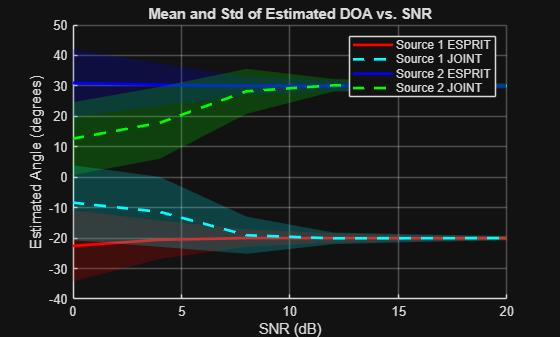

figure;
hold on;

% Define distinguishable colors for ESPRIT and JOINT estimates
esprit_colors = {'r', 'b'};             % Solid colors for ESPRIT
joint_colors = {'c', 'g' };             % Lighter shades for JOINT fills

for j = 1:d
    % Mean and bounds for ESPRIT
    mu = mean_theta(:, j);
    sigma = std_theta(:, j);
    upper = mu + sigma;
    lower = mu - sigma;

    % Mean and bounds for JOINT
    mu_joint = mean_theta_joint(:, j);
    sigma_joint = std_theta_joint(:, j);
    upper_joint = mu_joint + sigma_joint;
    lower_joint = mu_joint - sigma_joint;


    % Shaded error band for ESPRIT
    fill([SNR_dB'; flipud(SNR_dB')], [upper; flipud(lower)], ...
         esprit_colors{j}, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');

    % Mean line for ESPRIT
    plot(SNR_dB, mu, 'Color', esprit_colors{j}, 'LineWidth', 2);

    % Shaded error band for JOINT (lighter color)
    fill([SNR_dB'; flipud(SNR_dB')], [upper_joint; flipud(lower_joint)], ...
         joint_colors{j}, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');

    % Mean line for JOINT (dashed, same color as ESPRIT)
    plot(SNR_dB, mu_joint, 'Color', joint_colors{j}, 'LineWidth', 2, 'LineStyle', '--');
end

xlabel('SNR (dB)');
ylabel('Estimated Angle (degrees)');
legend('Source 1 ESPRIT', 'Source 1 JOINT', 'Source 2 ESPRIT', 'Source 2 JOINT');
title('Mean and Std of Estimated DOA vs. SNR');
grid on;

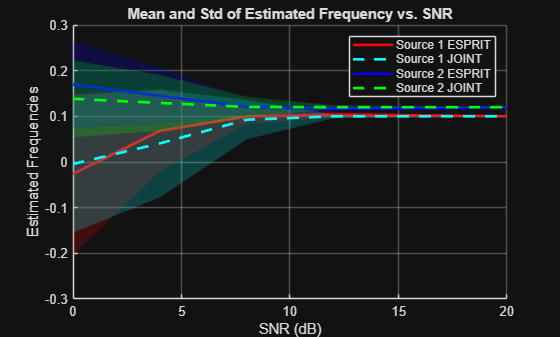

figure;
hold on;

% Define distinguishable colors
esprit_colors = {'r', 'b'};             % Solid for ESPRIT
joint_colors  = {'c', 'g'};             % Dashed and lighter for JOINT

for j = 1:d
    % ESPRIT stats
    mu_esprit = mean_phi(:, j);
    sigma_esprit = std_phi(:, j);
    upper_esprit = mu_esprit + sigma_esprit;
    lower_esprit = mu_esprit - sigma_esprit;

    % JOINT stats
    mu_joint = mean_phi_joint(:, j);
    sigma_joint = std_phi_joint(:, j);
    upper_joint = mu_joint + sigma_joint;
    lower_joint = mu_joint - sigma_joint;

    % Shaded error band for ESPRIT
    fill([SNR_dB'; flipud(SNR_dB')], [upper_esprit; flipud(lower_esprit)], ...
         esprit_colors{j}, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');

    % ESPRIT mean line
    plot(SNR_dB, mu_esprit, 'Color', esprit_colors{j}, 'LineWidth', 2);

    % Shaded error band for JOINT
    fill([SNR_dB'; flipud(SNR_dB')], [upper_joint; flipud(lower_joint)], ...
         joint_colors{j}, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');

    % JOINT mean line
    plot(SNR_dB, mu_joint, 'Color', joint_colors{j}, 'LineWidth', 2, 'LineStyle', '--');
end

xlabel('SNR (dB)');
ylabel('Estimated Frequencies');
legend('Source 1 ESPRIT', 'Source 1 JOINT', 'Source 2 ESPRIT', 'Source 2 JOINT');
title('Mean and Std of Estimated Frequency vs. SNR');
grid on;

## ZF Beamformer

M = 3;
N = 20;
d = 2;
delta = 1/2;
theta_true = [-20; 30];
f_true = [0.1; 0.12];
SNR = 1e6;
[X, A_true, S] = gendata(M, N, delta, theta_true, f_true, SNR);

#### A is known

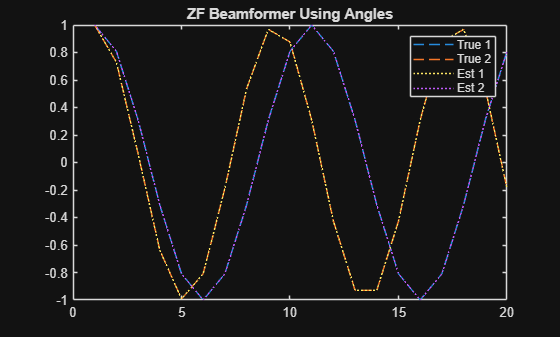

theta_est = esprit(X, d);
W_theta = compute_ZF_using_theta(theta_est, M);
S_theta = W_theta' * X; 

figure;
plot(real(S.'), '--'); hold on;
plot(real(S_theta.'), 'LineStyle',':'); title('ZF Beamformer Using Angles');
legend('True 1','True 2','Est 1','Est 2');

#### S is known

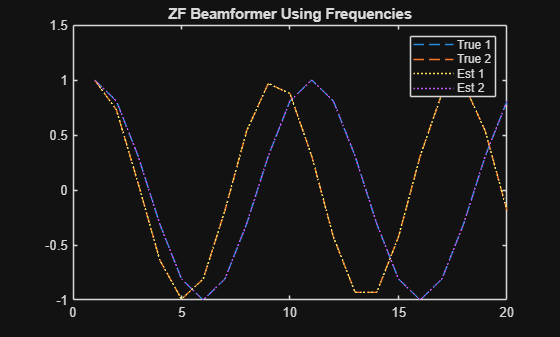

phi_est = espritfreq(X, d);
W_phi = compute_ZF_using_phi(phi_est, N, X);
S_phi = W_phi' * X;

figure;
plot(real(S.'), '--'); hold on;
plot(real(S_phi.'), 'LineStyle',':'); title("ZF Beamformer Using Frequencies");
legend('True 1','True 2','Est 1','Est 2');

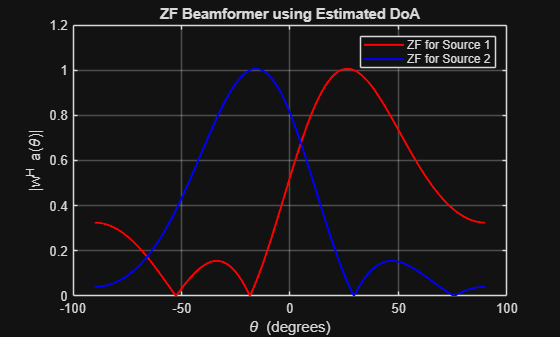

%% spatial response
M = 3;
N = 20;
d = 2;
delta = 1/2;
theta_true = [-20; 30];
f_true = [0.1; 0.12];
theta_scan = linspace(-90,90,1000);

SNR = 10; 
[X, A_true, S] = gendata(M, N, delta, theta_true, f_true, SNR);

theta_est = esprit(X, d);
% steering matrix from angle estimates
W_theta = compute_ZF_using_theta(theta_est, M);
S_theta = W_theta' * X; 

phi_est = espritfreq(X, d);
W_phi = compute_ZF_using_phi(phi_est, N, X);
S_phi = W_phi' * X;

num_angles = length(theta_scan);
y_theta_resp = zeros(d, num_angles);
y_phi_resp = zeros(d, num_angles);
for idx = 1:num_angles
    theta_test = theta_scan(idx);
    a_theta = exp(1j * 2 * pi * delta * (0:M-1).' * sind(theta_test));  % Mx1

    for k = 1:d
        y_theta_resp(k, idx) = abs(W_theta(:, k)' * a_theta);  % the actual DoA based on the ZF
        y_phi_resp(k, idx) = abs(W_phi(:, k)' * a_theta);
    end
end
figure;
plot(theta_scan, y_theta_resp(1,:), 'r', 'LineWidth', 1.5);  hold on;
plot(theta_scan, y_theta_resp(2,:), 'b', 'LineWidth', 1.5);
xlabel('\theta (degrees)'); ylabel('|w^H a(\theta)|'); grid on;
legend("ZF for Source 1", "ZF for Source 2");
title("ZF Beamformer using Estimated DoA");

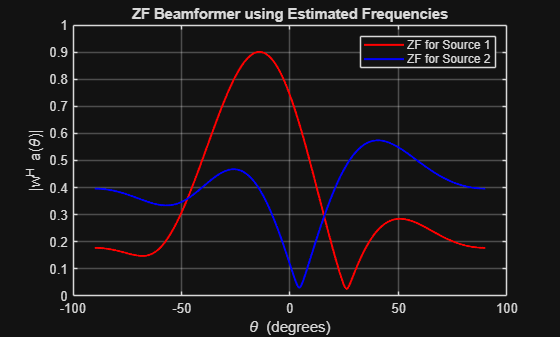

figure;
plot(theta_scan, y_phi_resp(1,:), 'r', 'LineWidth', 1.5); hold on;
plot(theta_scan, y_phi_resp(2,:), 'b', 'LineWidth', 1.5);
xlabel('\theta (degrees)'); ylabel('|w^H a(\theta)|'); grid on;
legend("ZF for Source 1", "ZF for Source 2");
title("ZF Beamformer using Estimated Frequencies");